# Procesamiento de imágenes en dados

### 0. Entorno MATLAB LiveScript

Limpieza del entorno de trabajo

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

Se añade al path el directorio donde se encuentra el script

% Obtener la ruta completa del script activo
ruta_completa_script = matlab.desktop.editor.getActiveFilename;

% Obtener la carpeta que contiene al script activo
carpeta_script = fileparts(ruta_completa_script);

% Añadir al path
addpath(carpeta_script)

### 1. Selección de dataset de imagenes relevantes

Se trabajará con el set de datos DiceDataset.zip, se trata de un conjunto de imágenes de dados de 6 caras, vistos desde arriba.

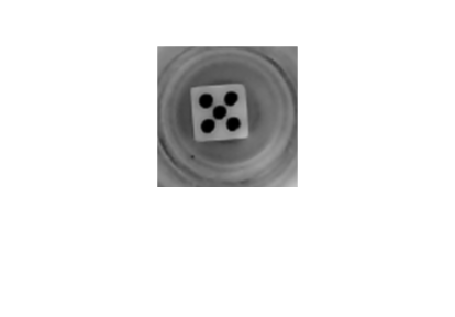

% Specify the zip file
zipFileName = 'DiceDataset.zip';

% If the dataset doesn't exist, unzip it
if ~exist('DiceDataset', 'dir')
    % Extract the contents
    unzip(zipFileName);
end

% Load the image
img = imread('DiceDataset/5/00100.bmp');
imshow(img)

### 2. Exploración visual para identificar alguna característica relevante

Inicialmente vemos el formato que tiene un dado, y nos gustaría saber que valor del 1 al 6 tiene de manera automática. Esto podría tener aplicación para un casino o si quisiésemos crear un bot que con computer vision tuviese una herramienta para videojuegos que incluyan dados.

Por tanto, característica a obtener: **Valor del dado**

### 3. Algoritmo para obtener la característica elegida

#### 3.1. Preprocesamiento

En este apartado se estudia como es el formato de la imágenes y se preparan para definir el algoritmo:

% Show the dimensions of the image
[numRows, numCols, numColorChannels] = size(img);
fprintf('Image size is %d rows x %d columns x %d color channels.\n', numRows, numCols, numColorChannels);

Image size is 128 rows x 128 columns x 1 color channels.


if numColorChannels == 1
    fprintf('The image is a single channel image (a grayscale image).\n');
end

The image is a single channel image (a grayscale image).


De inicio se trata de imágenes de 128x128 pixels con un único color, por tanto nos encontramos en escala de grises directamente.

Para simplificar y dado que el dado dado es blanco y negro nos interesa binarizar la imagen con un threshold. Podemos probar con varios thresholds. Por ejemplo 128:

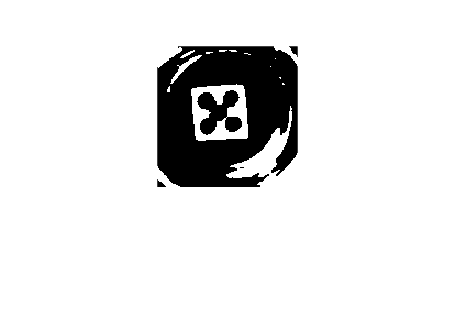

level = 0.5;
bw = img > level*255;
imshow(bw)

El resultado obtenido es interesante, no obstante cuando busquemos identificar el dado en la imagen tendremos varias zonas blancas.

MATLAB dispone de funcionalidades que permiten la binarización adaptativa:

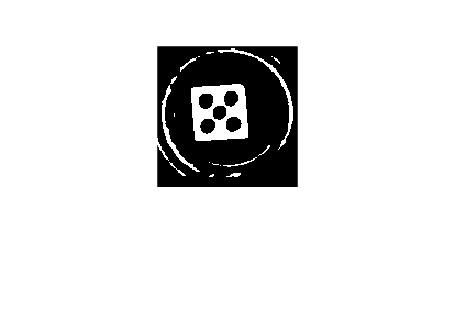

bw = imbinarize(img, 'adaptive');
imshow(bw)

Esto nos ayuda considerablemente y lo podemos aplicar gracias al contraste existente en este tipo de imágenes.